# Open Loop Analysis

## AFC Set UP

clear;
global fi_flag_Simulink
newline = sprintf('\n');
fc_afc = struct();
fc_afc.altitude = 10000;
fc_afc.velocity = 350;
FC_flag = 1; % Trim for steady wings-level flight
thrust = 5000;          % thrust, lbs
elevator = -0.09;       % elevator, degrees
alpha = 8.49;              % AOA, degrees
rudder = -0.01;             % rudder angle, degrees
aileron = 0.01;            % aileron, degrees
disp('Trimming Low Fidelity Model AFC:');

Trimming Low Fidelity Model AFC:


fi_flag_Simulink = 0;
[trim_state_lo, trim_thrust_lo, trim_control_lo, dLEF, xu_lo] = trim_F16_Modified(thrust, elevator, alpha, aileron, rudder, fc_afc.velocity, fc_afc.altitude, FC_flag,2);

Trim Values and Cost:
cost   = 9.0255e-30
thrust = 2549.7407 lb
elev   = -3.8466 deg
ail    = -3.5741e-16 deg
rud    = -1.8619e-14 deg
alpha  = 8.8116 deg
dLEF   = 0 deg
Vel.   = 350ft/s


trim_state_lin = trim_state_lo; trim_thrust_lin = trim_thrust_lo; trim_control_lin = trim_control_lo;
operating_point = operpoint('LIN_F16Block'); % retrieves initial conditions from integrators
operating_point.Inputs(1).u = trim_thrust_lin; operating_point.Inputs(2).u = trim_control_lin(1);
operating_point.Inputs(3).u = trim_control_lin(2); operating_point.Inputs(4).u = trim_control_lin(3);
SS_lo_AFC = linearize('LIN_F16Block');
long_states = [3 5 7 8 11 13 14];
long_inputs = [1 2];
long_outputs = [3 5 7 8 11];
SS_long_lo_AFC = ss(SS_lo_AFC.A(long_states,long_states), SS_lo_AFC.B(long_states,long_inputs), SS_lo_AFC.C(long_outputs,long_states), SS_lo_AFC.D(long_outputs,long_inputs));
SS_long_lo_AFC.StateName = SS_lo_AFC.StateName(long_states);
SS_long_lo_AFC.InputName= SS_lo_AFC.InputName(long_inputs);
lat_states = [4 6 7 9 10 12 13 15 16];
lat_inputs = [1 3 4];
lat_outputs = [4 6 7 9 10 12];
SS_lat_lo_AFC = ss(SS_lo_AFC.A(lat_states,lat_states), SS_lo_AFC.B(lat_states,lat_inputs), SS_lo_AFC.C(lat_outputs,lat_states), SS_lo_AFC.D(lat_outputs,lat_inputs));
SS_lat_lo_AFC.StateName = SS_lo_AFC.StateName(lat_states);
SS_lat_lo_AFC.InputName= SS_lo_AFC.InputName(lat_inputs);
disp(' ');

## Longitudinal State Space

disp('Longitudinal State Space');

Longitudinal State Space


lon_A = SS_long_lo_AFC.A;
lon_C = SS_long_lo_AFC.C;
lon_D = SS_long_lo_AFC.D;
lon_A;
lon_A(1,:) = [];
lon_A(:,1) = [];
lon_A(5:6,:) = [];
lon_A(:,5:6) = [];
lon_B = SS_long_lo_AFC.A(:,7);
lon_B(1,:) = [];
lon_B(5:6,:) = [];
lon_C(1,:) = [];
lon_C(:,1) = [];
lon_C(:,5:6) = [];
lon_D(:,1) = [];
lon_D(1,:) = [];
long_states_name = {'theta' 'v' 'alpha' 'q'};
long_inputs_name = {'d_e'};
long_outputs_name = {'theta' 'v' 'alpha' 'q'};
lon_sys = ss(lon_A,lon_B,lon_C,lon_D,"statename", long_states_name, "inputname", long_inputs_name, "outputname",long_outputs_name)

lon_sys =
 
  A = 
               theta           v       alpha           q
   theta           0           0           0           1
   v          -32.17     -0.0226      -7.183      -2.382
   alpha   -1.76e-13  -0.0005152     -0.5261       0.927
   q               0  -4.156e-18      -1.233     -0.7914
 
  B = 
                d_e
   theta          0
   v        0.00877
   alpha  -0.001118
   q       -0.06568
 
  C = 
          theta      v  alpha      q
   theta   57.3      0      0      0
   v          0      1      0      0
   alpha      0      0   57.3      0
   q          0      0      0   57.3
 
  D = 
          d_e
   theta    0
   v        0
   alpha    0
   q        0
 
Continuous-time state-space model.


disp('')

## Lateral State Space

disp('Lateral State Space');

Lateral State Space


lat_A = SS_lat_lo_AFC.A;
lat_C = SS_lat_lo_AFC.C;
lat_D = SS_lat_lo_AFC.D;
lat_A(2:3,:) = [];
lat_A(5:7,:) = [];
lat_A(:,2:3) = [];
lat_A(:,5:7) = [];
lat_B = SS_lat_lo_AFC.A(:,8:9);
lat_B(2:3,:) = [];
lat_B(5:7,:) = [];
lat_C(2:3,:) = [];
lat_C(:,2:3) = [];
lat_C(:,5:7) = [];
lat_D(:,1) = [];
lat_D(2:3,:) = [];
lat_states_name = {'Phi' 'beta' 'p' 'r'};
lat_inputs_name = {'d_a' 'd_r'};
lat_outputs_name = {'Phi' 'beta' 'p' 'r'};
lat_sys = ss(lat_A,lat_B,lat_C,lat_D, "statename", lat_states_name, "inputname", lat_inputs_name, "outputname",lat_outputs_name)

lat_sys =
 
  A = 
              Phi      beta         p         r
   Phi          0         0         1     0.155
   beta   0.09083    -0.166    0.1546   -0.9822
   p            0    -17.24    -1.717    0.7855
   r            0     3.407  -0.03789   -0.2457
 
  B = 
               d_a        d_r
   Phi           0          0
   beta  0.0001415  0.0004153
   p       -0.2454  -0.007812
   r      -0.01284   -0.02835
 
  C = 
          Phi  beta     p     r
   Phi   57.3     0     0     0
   beta     0  57.3     0     0
   p        0     0  57.3     0
   r        0     0     0  57.3
 
  D = 
         d_a  d_r
   Phi     0    0
   beta    0    0
   p       0    0
   r       0    0
 
Continuous-time state-space model.


disp(' ');

## Longitudinal Motion

[w_n_lon,zeta_lon,p_lon] = damp(lon_sys);
disp('Short Period Characteristics');

Short Period Characteristics


pole_sp = p_lon(3:4)

pole_sp =   -0.6648 + 1.0567i
  -0.6648 - 1.0567i


n_freq_sp = w_n_lon(3)

n_freq_sp = 1.2484

zeta_sp = zeta_lon(3)

zeta_sp = 0.5325

P_sp = 2 *pi / imag(p_lon(3))

P_sp = 5.9460

T_half_sp = log(1/2) / real(pole_sp(1))

T_half_sp = 1.0427

disp(' ');

disp('Phugoid Characteristics');

Phugoid Characteristics


pole_ph = p_lon(1:2)

pole_ph =   -0.0053 + 0.1144i
  -0.0053 - 0.1144i


n_freq_ph = w_n_lon(1)

n_freq_ph = 0.1145

zeta_ph = zeta_lon(1)

zeta_ph = 0.0459

P_ph = 2 *pi / imag(p_lon(1))

P_ph = 54.9212

T_half_ph = log(1/2) / real(pole_ph(1))

T_half_ph = 131.7375

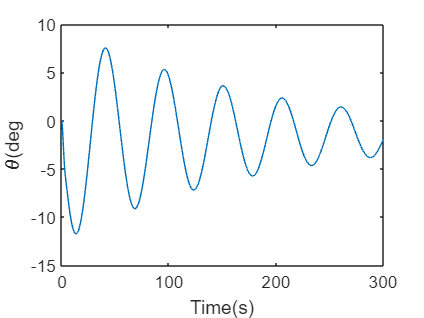

t1 = linspace(0,300,3000);
t2 = linspace (0,20,200);
y_out_phugoid = step(lon_sys,t1);
y_out_sp = step(lon_sys,t2);
%Phugoid Plots
plot(t1,y_out_phugoid(:,1))
xlabel('Time(s)')
ylabel('\theta(deg')

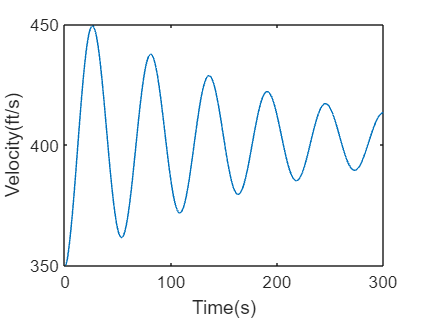

plot(t1,y_out_phugoid(:,2)+350)
xlabel('Time(s)')
ylabel('Velocity(ft/s)')

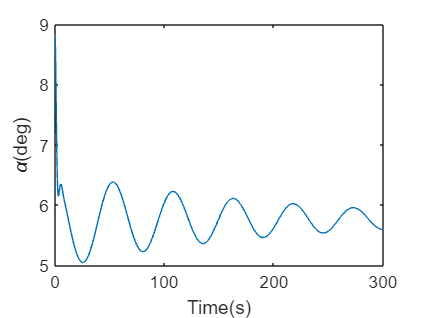

plot(t1,y_out_phugoid(:,3)+xu_lo(8)*180/pi)
xlabel('Time(s)')
ylabel('\alpha(deg)')

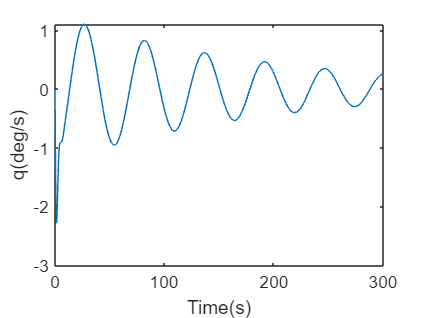

plot(t1,y_out_phugoid(:,4))
xlabel('Time(s)')
ylabel('q(deg/s)')

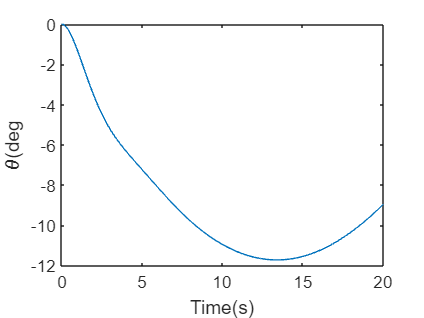

%Short Period Plots
plot(t2,y_out_sp(:,1))
xlabel('Time(s)')
ylabel('\theta(deg')

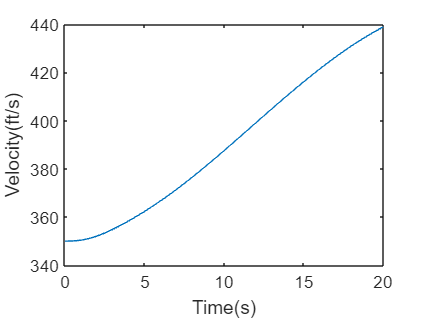

plot(t2,y_out_sp(:,2)+350)
xlabel('Time(s)')
ylabel('Velocity(ft/s)')

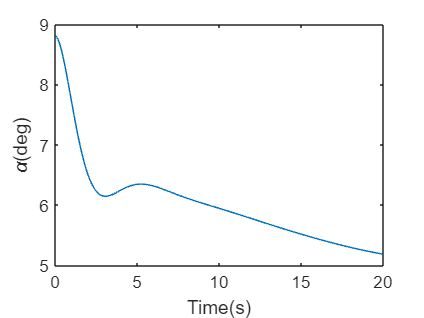

plot(t2,y_out_sp(:,3)+xu_lo(8)*180/pi)
xlabel('Time(s)')
ylabel('\alpha(deg)')

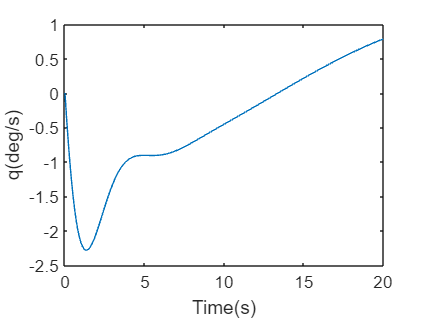

plot(t2,y_out_sp(:,4))
xlabel('Time(s)')
ylabel('q(deg/s)')

## Lateral Motion

[w_n_lat,zeta_lat,p_lat] = damp(lat_sys);
disp('Dutch Roll Characteristics');

Dutch Roll Characteristics


pole_dr = p_lat(3:4)

pole_dr =   -0.3532 + 2.3773i
  -0.3532 - 2.3773i


n_freq_dr = w_n_lat(3)

n_freq_dr = 2.4033

zeta_dr = zeta_lat(3)

zeta_dr = 0.1470

P_dr = 2 *pi / imag(p_lat(3))

P_dr = 2.6430

T_half_dr = log(1/2) / real(pole_dr(1))

T_half_dr = 1.9625

disp(' ');

disp('Aperiod Roll Characteristics');

Aperiod Roll Characteristics


pole_ap = p_lat(2)

pole_ap = -1.4165

n_freq_ap = w_n_lat(2)

n_freq_ap = 1.4165

T_constant_ap = -1/real(pole_ap)

T_constant_ap = 0.7060

T_half_ap = log(1/2) / real(pole_ap)

T_half_ap = 0.4893

disp(' ');

disp('Spiral Characteristics');

Spiral Characteristics


pole_spiral = p_lat(1)

pole_spiral = -0.0061

n_freq_spiral = w_n_lat(1)

n_freq_spiral = 0.0061

T_constant_spiral = -1/real(pole_spiral)

T_constant_spiral = 162.9035

T_half_spiral = log(1/2) / real(pole_spiral)

T_half_spiral = 112.9161

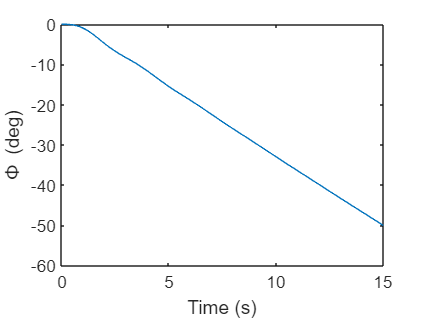

t3 = linspace(0,15,150);
t4 = linspace(0,400,4000);
y_out_lat = step(lat_sys,t3);
y_out_lat_spiral = step(lat_sys,t4);
%Dutch Roll Plots
plot(t3,y_out_lat(:,1,2))
xlabel('Time (s)')
ylabel('\Phi (deg)')

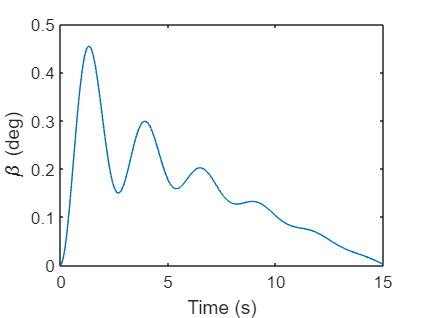

plot(t3,y_out_lat(:,2,2))
xlabel('Time (s)')
ylabel('\beta (deg)')

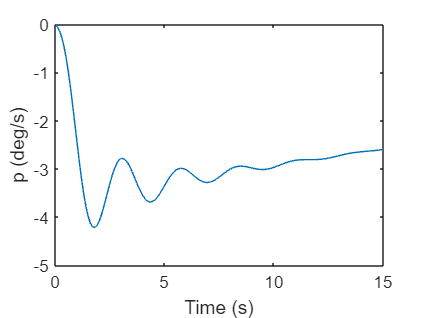

plot(t3,y_out_lat(:,3,2))
xlabel('Time (s)')
ylabel('p (deg/s)')

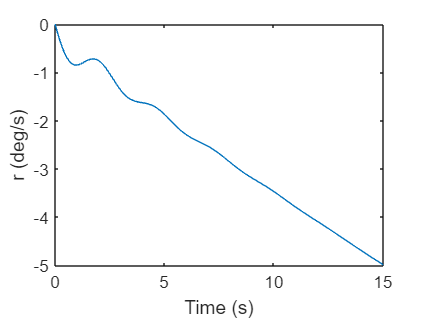

plot(t3,y_out_lat(:,4,2))
xlabel('Time (s)')
ylabel('r (deg/s)')

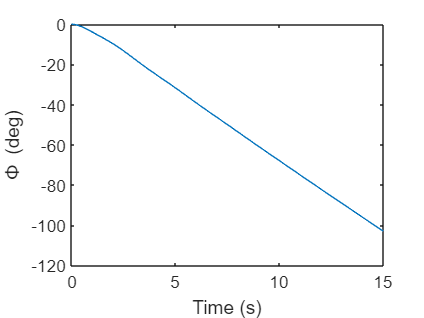

%Aperiodic Roll Plots
plot(t3,y_out_lat(:,1,1))
xlabel('Time (s)')
ylabel('\Phi (deg)')

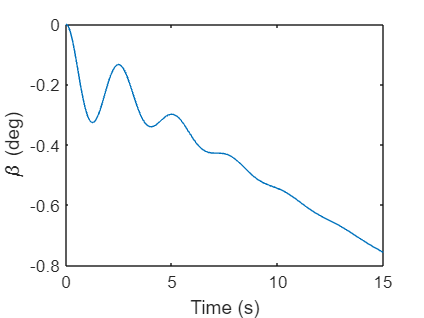

plot(t3,y_out_lat(:,2,1))
xlabel('Time (s)')
ylabel('\beta (deg)')

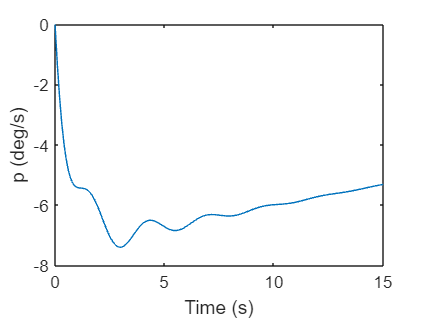

plot(t3,y_out_lat(:,3,1))
xlabel('Time (s)')
ylabel('p (deg/s)')

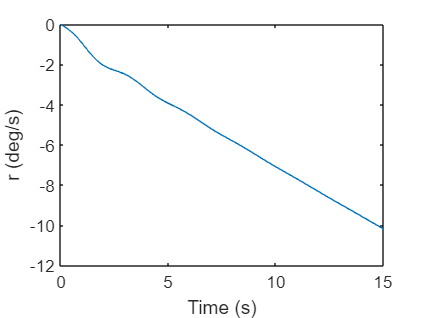

plot(t3,y_out_lat(:,4,1))
xlabel('Time (s)')
ylabel('r (deg/s)')

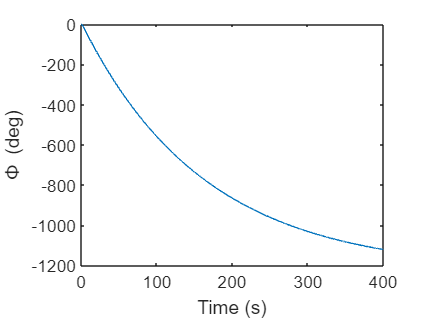

%Spirla Roll Plots
plot(t4,y_out_lat_spiral(:,1,1))
xlabel('Time (s)')
ylabel('\Phi (deg)')

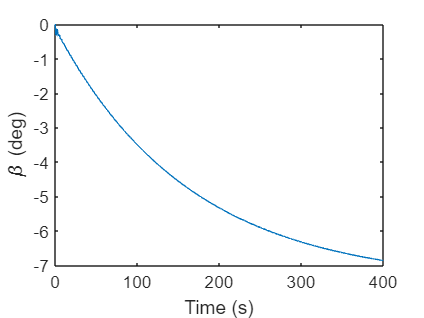

plot(t4,y_out_lat_spiral(:,2,1))
xlabel('Time (s)')
ylabel('\beta (deg)')

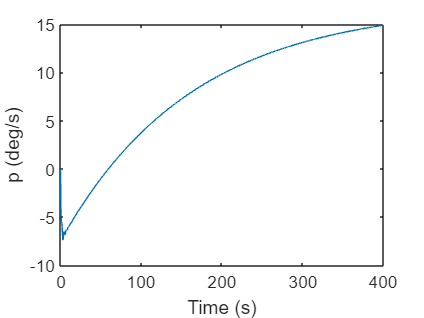

plot(t4,y_out_lat_spiral(:,3,1))
xlabel('Time (s)')
ylabel('p (deg/s)')

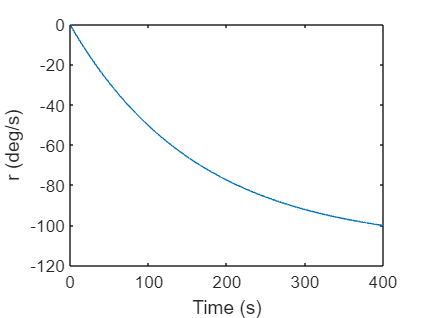

plot(t4,y_out_lat_spiral(:,4,1))
xlabel('Time (s)')
ylabel('r (deg/s)')